This script analyzes the correlation between the timecourses of independent components from a resting-state dataset and whisker motion.

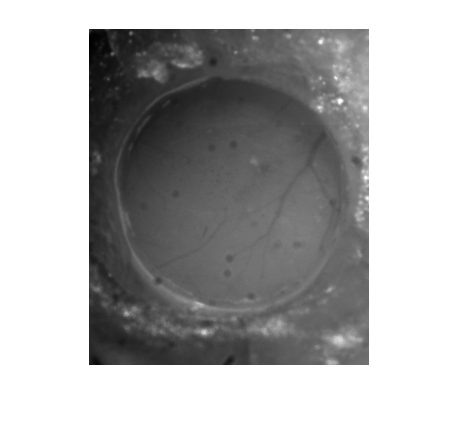

%Extract and pre-process brain imaging data
dataFolderPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_CIB_N30';
greenMovie = ImagingMovie(dataFolderPath,'green');
greenMovie.correctMotion;
redMovie = ImagingMovie(dataFolderPath,'red');
redMovie.correctMotion;

speckleContrastMovie = ImagingMovie(dataFolderPath,'speckle');
speckleContrastMovie.correctMotion;
greenMovie.normalizeByMean;
redMovie.normalizeByMean;
[HbOMovie, HbRMovie] = convertToHb(greenMovie.data,redMovie.data);
speckleContrastMovie.convertToSpeckleContrast(5);
HbOMovie = ImagingMovie(dataFolderPath,'HbO',HbOMovie);
HbRMovie = ImagingMovie(dataFolderPath,'HbR',HbRMovie);
clear greenMovie redMovie
HbOMovie.gaussianFilter(1);
HbRMovie.gaussianFilter(1);
speckleContrastMovie.gaussianFilter(1);
HbOMovie.zscore;
HbRMovie.zscore;
speckleContrastMovie.zscore;
mask = HbOMovie.createMask;
HbOMovie.applyMask(mask);
HbRMovie.applyMask(mask);
speckleContrastMovie.applyMask(mask);

%Extract independent components and their timecourses
HbOMatrix = HbOMovie.convertTo2DMatrix(mask);
HbRMatrix = HbRMovie.convertTo2DMatrix(mask);
SCMatrix = speckleContrastMovie.convertTo2DMatrix(mask);
n = 10;
[componentsHbO, wHbO, tHbO] = fastICA(HbOMatrix,n,'negentropy');
[componentsHbR, wHbR, tHbR] = fastICA(HbRMatrix,n,'negentropy');
[componentsSC, wSC, tSC] = fastICA(SCMatrix,n,'negentropy');
A_HbO = tHbO\wHbO'; %A is the matrix that holds the mixing weights
A_HbO = (A_HbO-mean(A_HbO))./std(A_HbO);
A_HbR = tHbO\wHbR';
A_HbR = (A_HbR-mean(A_HbR))./std(A_HbR);
A_SC = tSC\wSC';
A_SC = (A_SC-mean(A_SC))./std(A_SC);

%Extract whisker motion signal
videoPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.avi';
syncFilePath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.mat';
monitoringVideo = webcamMovie(videoPath,syncFilePath);
whiskerMask = monitoringVideo.createMask;
rawWhiskerSignal = monitoringVideo.extractROIsignal(whiskerMask);

whiskerSignal = monitoringVideo.synchronizeSignal(rawWhiskerSignal);
whiskerSignal = (whiskerSignal-mean(whiskerSignal))/std(whiskerSignal);
whiskerME = [0 ;abs(diff(whiskerSignal))]; %add initial zero to make vectors same size
whiskerME = (whiskerME-mean(whiskerME))/std(whiskerME);

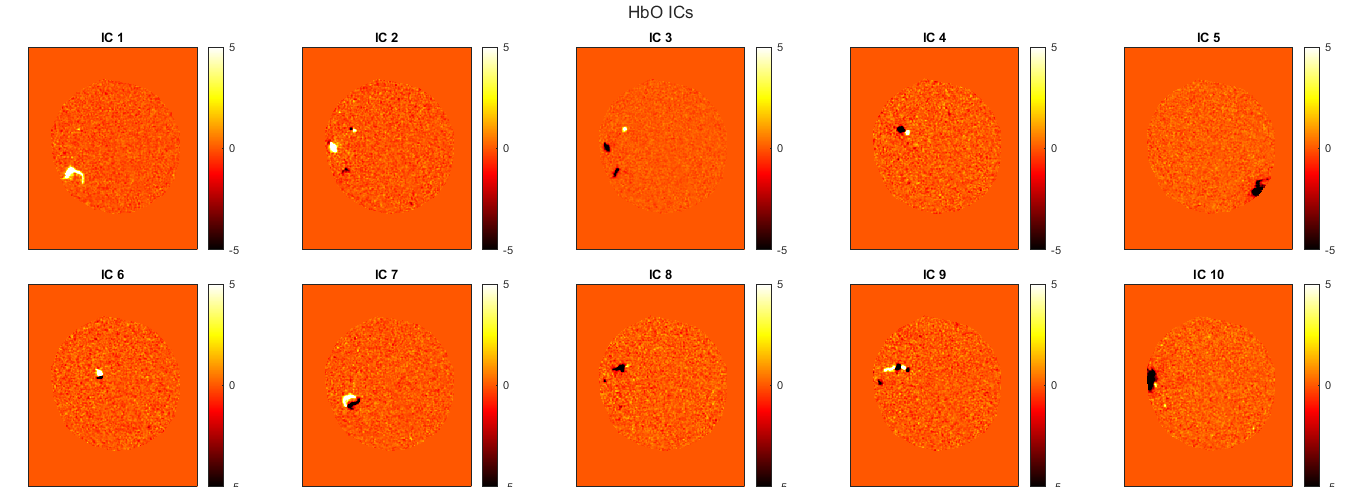

%Display independent components
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO ICs';
for i = 1:n
    nexttile;
    map(find(mask))=componentsHbO(i,:);
    imagesc(map,[-5 5]);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

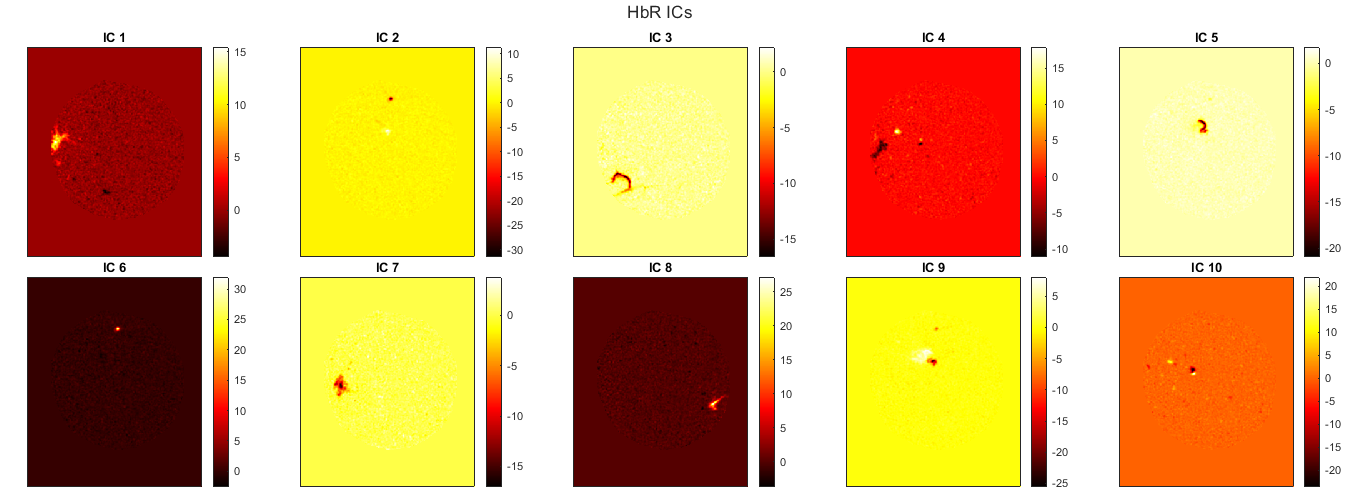


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'HbR ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsHbR(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

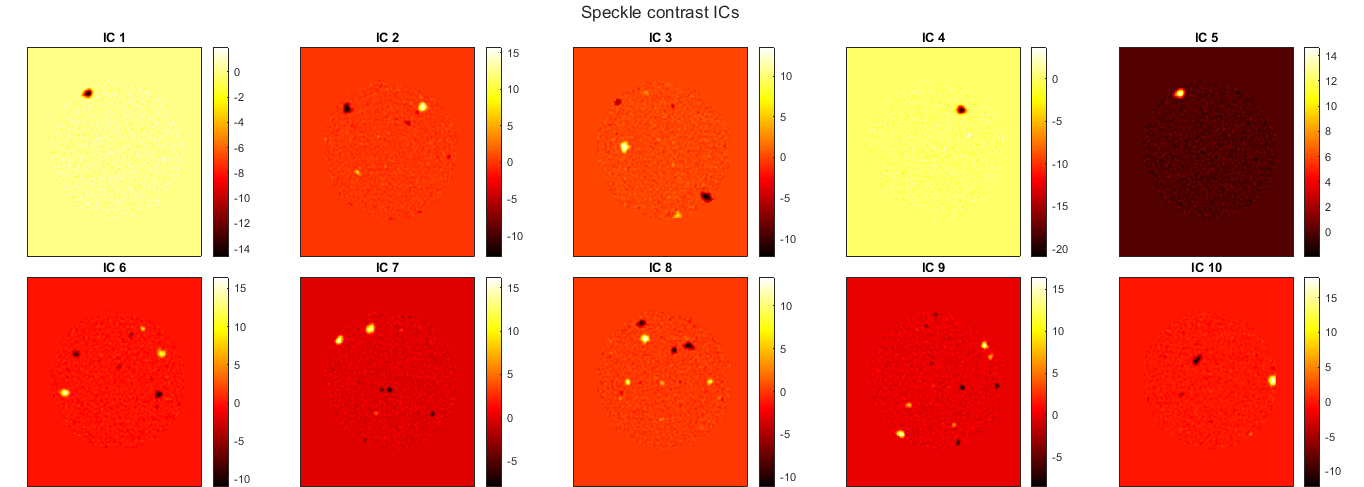


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'Speckle contrast ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsSC(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

The time courses betweem whisker motion energy and ICs are now visualized.

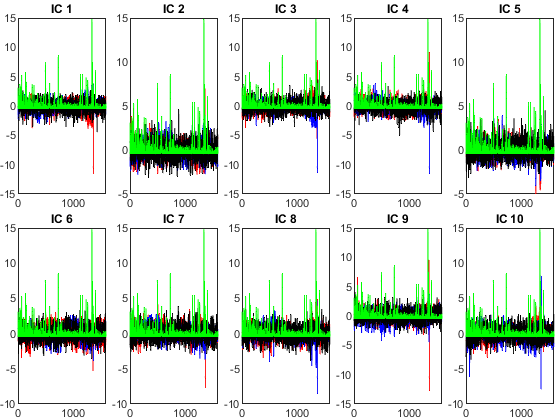

figure;
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
for i=1:n
    nexttile;
    plot(A_HbO(:,i),'Color','r');
    hold on
    plot(A_HbR(:,i),'Color','b');
    plot(A_SC(:,i),'Color','k');
    plot(whiskerME,'Color','g');
    title(['IC ' num2str(i)]);
end

To quantify their relationship, we calculate their correlation. To consider possible delays between whisker motion and its translation to hemodynamics, as well as possible synchronization errors between signals, we instead compute the maximum of their cross-correlation in a ± 3 s range.

crossCorrsHbO = zeros(2,n);
crossCorrsHbR = zeros(2,n);
crossCorrsSC = zeros(2,n);
freq = HbOMovie.freq;
range = round(3*freq);
for i = 1:n   
    [corrMax,lag] = findCrossCorrMax(A_HbO(:,i),whiskerME,range);
    crossCorrsHbO(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_HbR(:,i),whiskerME,range);
    crossCorrsHbR(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_SC(:,i),whiskerME,range);
    crossCorrsSC(:,i) = [corrMax;lag];
end

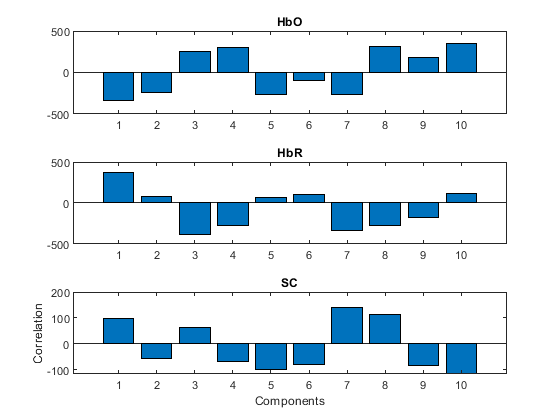

figure;
t = tiledlayout(3,1);
nexttile;
bar(crossCorrsHbO(1,:));
title('HbO');
nexttile;
bar(crossCorrsHbR(1,:));
title('HbR');
nexttile;
bar(crossCorrsSC(1,:));
title('SC');
xlabel('Components');
ylabel('Correlation');

Try repeating the analysis but by first bandpass filtering the signals.

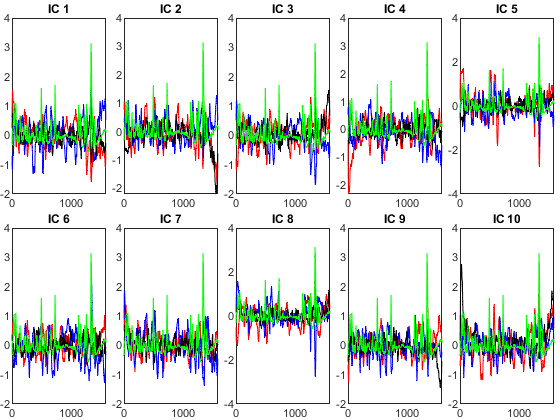

freqRange = [0.1 1];
[b,a] = cheby1(1,3,freqRange/freq);
whiskerME_filt = filtfilt(b,a,whiskerME);
A_HbO_filt = filtfilt(b,a,double(A_HbO));
A_HbR_filt = filtfilt(b,a,double(A_HbR));
A_SC_filt = filtfilt(b,a,double(A_SC));
for i = 1:n   
    [corrMax,lag] = findCrossCorrMax(A_HbO_filt(:,i),whiskerME_filt,range);
    crossCorrsHbO(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_HbR_filt(:,i),whiskerME_filt,range);
    crossCorrsHbR(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_SC_filt(:,i),whiskerME_filt,range);
    crossCorrsSC(:,i) = [corrMax;lag];
end
figure;
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
for i=1:n
    nexttile;
    plot(A_HbO_filt(:,i),'Color','r');
    hold on
    plot(A_HbR_filt(:,i),'Color','b');
    plot(A_SC_filt(:,i),'Color','k');
    plot(whiskerME_filt,'Color','g');
    title(['IC ' num2str(i)]);
end

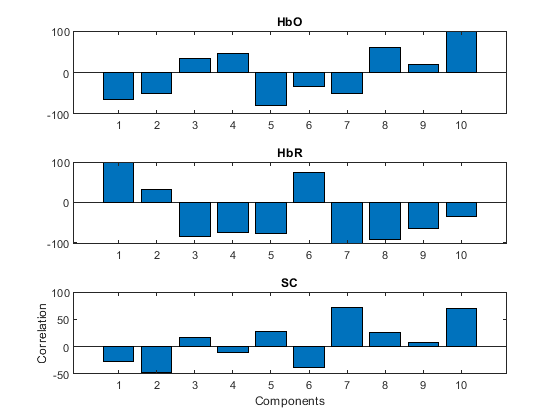

figure;
t = tiledlayout(3,1);
nexttile;
bar(crossCorrsHbO(1,:));
title('HbO');
nexttile;
bar(crossCorrsHbR(1,:));
title('HbR');
nexttile;
bar(crossCorrsSC(1,:));
title('SC');
xlabel('Components');
ylabel('Correlation');

There seems to be no major difference.

Try computing the ICs from a filtered signal.

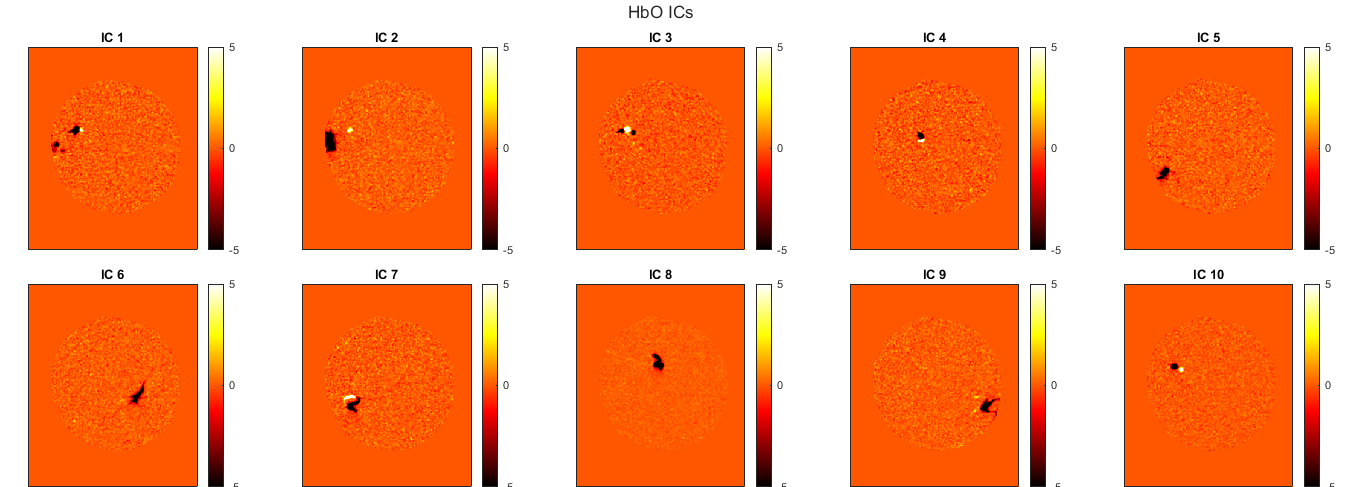

%Extract independent components and their timecourses
HbOMovie.bandPassFilter(0.01,1);
HbRMovie.bandPassFilter(0.01,1);
speckleContrastMovie.bandPassFilter(0.01,1);
HbOMatrix = HbOMovie.convertTo2DMatrix(mask);
HbRMatrix = HbRMovie.convertTo2DMatrix(mask);
SCMatrix = speckleContrastMovie.convertTo2DMatrix(mask);
n = 10;
[componentsHbO, wHbO, tHbO] = fastICA(HbOMatrix,n,'negentropy');
[componentsHbR, wHbR, tHbR] = fastICA(HbRMatrix,n,'negentropy');
[componentsSC, wSC, tSC] = fastICA(SCMatrix,n,'negentropy');
A_HbO = tHbO\wHbO'; %A is the matrix that holds the mixing weights
A_HbO = (A_HbO-mean(A_HbO))./std(A_HbO);
A_HbR = tHbO\wHbR';
A_HbR = (A_HbR-mean(A_HbR))./std(A_HbR);
A_SC = tSC\wSC';
A_SC = (A_SC-mean(A_SC))./std(A_SC);

%Display independent components
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO ICs';
for i = 1:n
    nexttile;
    map(find(mask))=componentsHbO(i,:);
    imagesc(map,[-5 5]);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

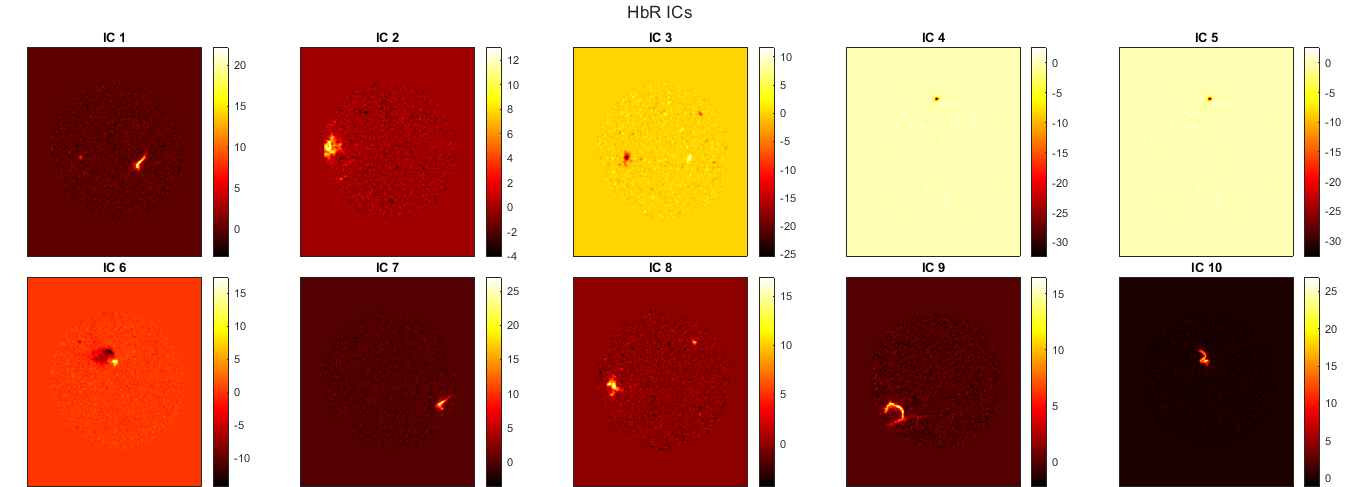


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'HbR ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsHbR(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

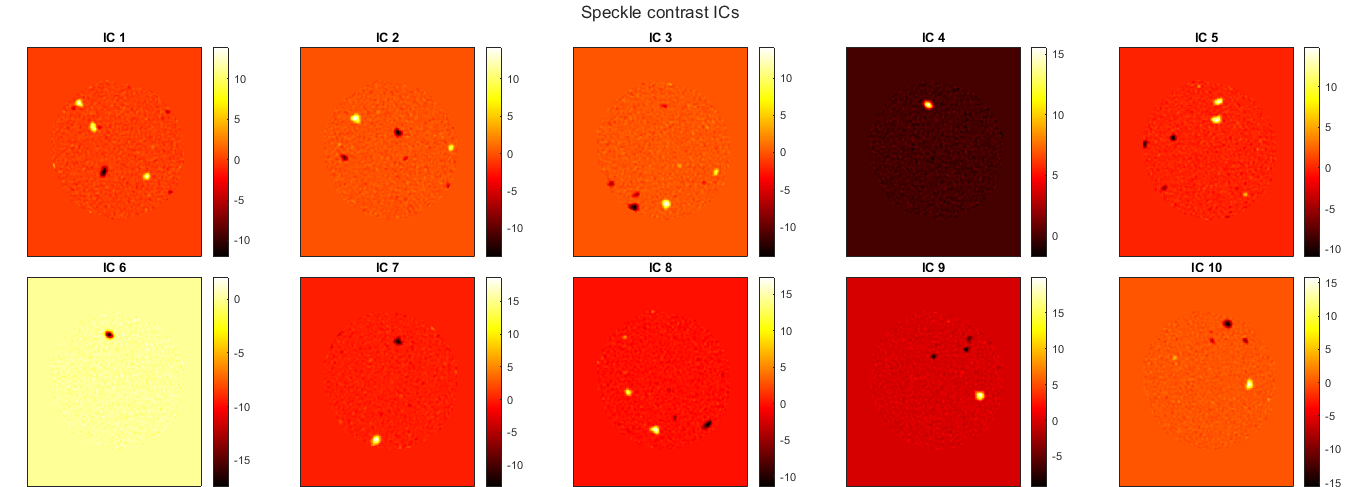


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'Speckle contrast ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsSC(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

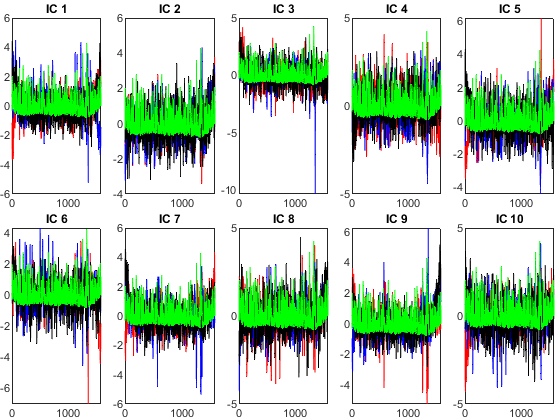

%Show time courses
[b,a] = cheby1(1,3,[0.01 1]/freq);
whiskerME_filt = filtfilt(b,a,whiskerME);
figure;
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
for i=1:n
    nexttile;
    plot(A_HbO(:,i),'Color','r');
    hold on
    plot(A_HbR(:,i),'Color','b');
    plot(A_SC(:,i),'Color','k');
    plot(whiskerME_filt,'Color','g');
    title(['IC ' num2str(i)]);
end

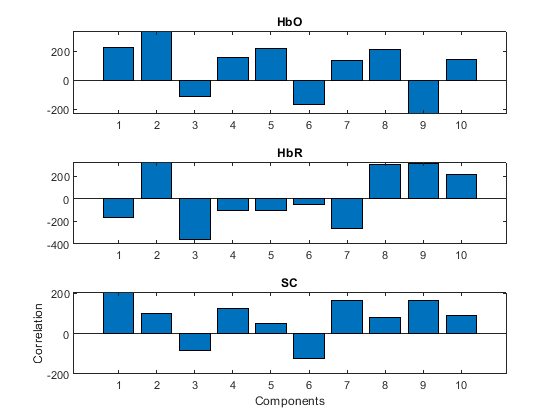

%Cross correlation analysis
for i = 1:n   
    [corrMax,lag] = findCrossCorrMax(A_HbO(:,i),whiskerME_filt,range);
    crossCorrsHbO(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_HbR(:,i),whiskerME_filt,range);
    crossCorrsHbR(:,i) = [corrMax;lag];
    [corrMax,lag] = findCrossCorrMax(A_SC(:,i),whiskerME_filt,range);
    crossCorrsSC(:,i) = [corrMax;lag];
end
figure;
t = tiledlayout(3,1);
nexttile;
bar(crossCorrsHbO(1,:));
title('HbO');
nexttile;
bar(crossCorrsHbR(1,:));
title('HbR');
nexttile;
bar(crossCorrsSC(1,:));
title('SC');
xlabel('Components');
ylabel('Correlation');